## SVM / PCA w. SVM

start_time = datetime('now')

start_time = datetime
   20-Mar-2025 19:41:08


clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks_Sense\Masks_GLCM_SVM_train\';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Paths to img and mask folders
img_dir = fullfile(orig_dir, 'img');
mask_dir = fullfile(orig_dir, 'mask');

% Get file lists
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

list_imgs_names = {list_imgs.name};
list_lbls_names = {list_lbls.name};

% Ensure they are sorted or correctly paired
list_imgs_names = sort(list_imgs_names);
list_lbls_names = sort(list_lbls_names);

% Check if the number of images and masks match
if length(list_imgs_names) ~= length(list_lbls_names)
    error('Mismatch between number of images and masks');
end

% Shuffle indices
num_files = length(list_imgs_names);
rand_indices = randperm(num_files); % Randomize order

% Split indices into 70% train, 30% test
split_ratio = 0.7;
train_count = round(split_ratio * num_files);
train_indices = rand_indices(1:train_count);
test_indices = rand_indices(train_count+1:end);

% Create training and testing lists
train_imgs_names = list_imgs_names(train_indices);
train_lbls_names = list_lbls_names(train_indices);
test_imgs_names = list_imgs_names(test_indices);
test_lbls_names = list_lbls_names(test_indices);

% Display counts
fprintf('Training set: %d images, %d masks\n', length(train_imgs_names), length(train_lbls_names));

Training set: 2659 images, 2659 masks


fprintf('Testing set: %d images, %d masks\n', length(test_imgs_names), length(test_lbls_names));

Testing set: 1140 images, 1140 masks



% Init
features_matrix= [];
labelsVec = [];
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Go through through folder
t1 = datetime('now');

% Get list of image and label files
list_train_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), train_imgs_names, 'UniformOutput', false) % Get images

list_train_imgs = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_train_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), train_lbls_names, 'UniformOutput', false) % Get labels

list_train_lbls = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_test_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), test_imgs_names, 'UniformOutput', false) % Get images

list_test_imgs = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre

list_test_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), test_lbls_names, 'UniformOutput', false) % Get labels

list_test_lbls = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre


% Ensure corresponding images and labels exist
if numel(list_train_imgs) ~= numel(list_train_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');
    t3 = datetime('now');

    for k = 1:numel(list_train_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);
                label_window = label(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});
                % High contrast is rough terrain (landlside)
                % Low E is more randomness (lanslide distrutpins)
                % High homogeneirty is uniform areas (vegetation or stable land)

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;
                features_matrix = [features_matrix; features]; % Append row

                % Assessing label - if 10% of pix in label is 1, mark as landlside
                if sum(label_window,'all') >= (window_size*window_size/10)
                    lbl = 1; % Landlside present
                else
                    lbl = 0; % No landslide
                end
                labelsVec = [labelsVec; lbl]; % Append label
            end
        end
        if ismember(k, 500:500:numel(list_train_imgs))
            t3 = datetime('now');
            elapsedTime = seconds(t3-t2); % Cacluate elapsed times
            fprintf("Total processing time after %s imgs: %.1fs\n", num2str(k), elapsedTime);   
            t2 = datetime('now');
        end
    end
end

Total processing time after 500 imgs: 73.5s
Total processing time after 1000 imgs: 153.1s
Total processing time after 1500 imgs: 220.8s
Total processing time after 2000 imgs: 277.3s
Total processing time after 2500 imgs: 355.7s


size(features_matrix)

ans =       382896           4


t4 = datetime('now')

t4 = datetime
   20-Mar-2025 20:01:18


elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total processing time after %s imgs: %.1fs\n", num2str(k), elapsedTime);

Total processing time after 2659 imgs: 1209.0s



save('C:/Users/andre/EE581-LandlideProj/src/pre_processing/SVM/svm_landslide_features_train.mat', 'features_matrix');
disp('Features saved');

Features saved


save('C:/Users/andre/EE581-LandlideProj/src/pre_processing/SVM/svm_landslide_features_labels_train.mat', 'labelsVec');
disp('Feature labels saved');

Feature labels saved


save('C:/Users/andre/EE581-LandlideProj/src/pre_processing/SVM/svm_landslide_features_and_labels_train.mat', 'features_matrix', 'labelsVec');
disp('Features and labels saved');

Features and labels saved



%% Now train SVM classifier with localisex feature vectors (classify if 10x10 
% portion of image is landlside via the features)
t5 = datetime('now')

t5 = datetime
   20-Mar-2025 20:01:19


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.069003 |       18719 |    0.069003 |    0.069003 |       522.67 |     0.033814 |         true |
|    2 | Best   |    0.056172 |      1520.9 |    0.056172 |    0.056804 |    0.0017437 |       3.1588 |         true |
|    3 | Accept |    0.056172 |      3048.1 |    0.056172 |    0.056175 |    0.0013824 |    0.0023435 |        false |
|    4 | Best   |    0.051505 |      7110.5 |    0.051505 |    0.051567 |       97.214 |       2.2261 |        false |


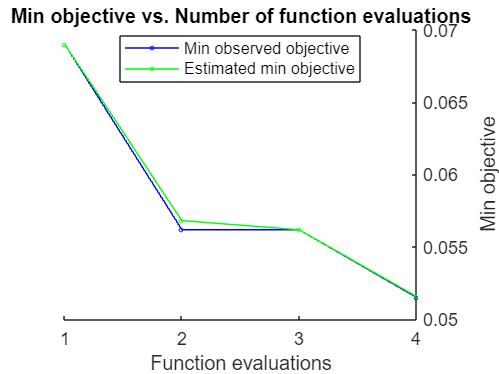


% Train SVM model
svmModel = fitcsvm(features_matrix, labelsVec, 'KernelFunction','rbf','KernelScale', ...
    'auto', 'Standardize',true, 'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))


t6 = datetime('now')

t6 = datetime
   21-Mar-2025 14:22:19


elapsedTime = seconds(t6-t5); % Cacluate elapsed times
fprintf("Training SVM time: %.1fs\n", elapsedTime);

Training SVM time: 66060.4s



% Save trained model
save('C:\Users\andre\EE581-LandlideProj\src\pre_processing\SVM\svm_landslide_model_train.mat', 'svmModel');

Error using save
Variable 'svmModel' not found.

disp('SVM trained and model saved');
saveLearnerForCoder(svmModel,'C:\Users\andre\EE581-LandlideProj\src\pre_processing\SVM\SVMIris_train');


% Set up stats storage
% Assign zero array of its image count
% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_test_imgs));
    false_pos = zeros(1,numel(list_test_imgs));
    true_neg = zeros(1,numel(list_test_imgs));
    false_neg = zeros(1,numel(list_test_imgs));
    precision = zeros(1,numel(list_test_imgs));
    recall = zeros(1,numel(list_test_imgs));
    f1_score = zeros(1,numel(list_test_imgs));
    accuracy = zeros(1,numel(list_test_imgs));
    correct_landslide = zeros(1,numel(list_test_imgs));

    local_true_pos = zeros(1,numel(list_test_imgs));
    local_false_pos = zeros(1,numel(list_test_imgs));
    local_true_neg = zeros(1,numel(list_test_imgs));
    local_false_neg = zeros(1,numel(list_test_imgs));
    local_precision = zeros(1,numel(list_test_imgs));
    local_recall = zeros(1,numel(list_test_imgs));
    local_f1_score = zeros(1,numel(list_test_imgs));
    local_accuracy = zeros(1,numel(list_test_imgs));
end

% Init
features = []
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions
% 
% t1 = datetime('now');
% t2 = datetime('now');
% t3 = datetime('now');
% t4 = datetime('now');
% t5 = datetime('now');
% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end


% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');
    t3 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'), 'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end
    for k = 1:numel(list_test_imgs)

        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        mask = zeros(rows, cols);
        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;

                % Predict Landlside or not
                predLabel = predict(svmModel, features);

                % Store result in mask
                mask(r:r+window_size-1,c:c+window_size-1) = predLabel; % Mark landlside area
            end
        end
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask

        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(test_imgs_names{k}, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t2); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Create folder to output plots
if ~exist(fullfile(output_dir,'Plots'), 'dir')
    mkdir(output_dir,'Plots');
end

% Plot statistics
figure;
plot(1:numel(list_test_imgs),correct_landslide);
xlabel('Image');
ylabel('Percentage [%]');
title("Correct Pixels");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
saveas(gcf, output_file); % Save current figure
close(gcf); % Close figure to avoid memory usage
figure;
plot(1:numel(list_test_imgs),accuracy*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Accuracy");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);
close(gcf);
figure;
plot(1:numel(list_test_imgs),precision*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Precision");
grid on;
ylim([0 100]);
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
plot(1:numel(list_test_imgs),recall*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Recall");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
plot(1:numel(list_test_imgs),f1_score*100);
xlabel('Image');
ylabel('Percentage [%]');
title("F1 Score");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

% Plot statistics
figure;
plot(1:numel(list_test_imgs),local_accuracy*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Accuracy (Landslide Pixels)");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
saveas(gcf, output_file);
close(gcf);
figure;
plot(1:numel(list_test_imgs),local_precision*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Precision (Landslide Pixels)");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
saveas(gcf, output_file);
close(gcf);
figure;
plot(1:numel(list_test_imgs),local_recall*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Recall (Landslide Pixels)");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
saveas(gcf, output_file);
close(gcf);
figure;
plot(1:numel(list_test_imgs),local_f1_score*100);
xlabel('Image');
ylabel('Percentage [%]');
title("F1 Score (Landslide Pixels)");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
saveas(gcf, output_file);
close(gcf);

overall_correct_landslide = mean(correct_landslide)
overall_precision = mean(precision)
overall_pix_precision = mean(local_precision)
overall_recall = mean(recall)
overall_pix_recall = mean(local_recall)
overall_f1_score = mean(f1_score)
overall_pix_f1_score = mean(local_f1_score)
overall_accuracy= mean(accuracy)
overall_pix_accuracy= mean(local_accuracy)

t4 = datetime('now');
elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total time: %.1fs", elapsedTime);    

clear all;


Using train and test data

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks_Sense\Masks_GLCM_SVM\';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Init
features_matrix = [];
labelsVec = [];
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');
    t3 = datetime('now');

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size
            for c = 1:window_size:cols-window_size
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);
                label_window = label(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});
                % High contrast is rough terrain (landlside)
                % Low E is more randomness (lanslide distrutpins)
                % High homogeneirty is uniform areas (vegetation or stable land)

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;
                features_matrix = [features_matrix; features]; % Append row

                % Assessing label - if 10% of pix in label is 1, mark as landlside
                if sum(label_window,'all') >= (window_size*window_size/10)
                    lbl = 1; % Landlside present
                else
                    lbl = 0; % No landslide
                end
                labelsVec = [labelsVec; lbl]; % Append label
            end
        end
        if ismember(k, 500:500:numel(list_imgs))
            t3 = datetime('now');
            elapsedTime = seconds(t3-t2); % Cacluate elapsed times
            fprintf("Total processing time after %s imgs: %.1fs\n", num2str(k), elapsedTime);   
            t2 = datetime('now');
        end
    end
end
size(features_matrix)
t4 = datetime('now');
elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total processing time after %s imgs: %.1fs\n", num2str(k), elapsedTime);

save('C:/Users/andre/EE581-LandlideProj/src/pre_processing/SVM/svm_landslide_features.mat', 'features_matrix');
disp('Features saved');
save('C:/Users/andre/EE581-LandlideProj/src/pre_processing/SVM/svm_landslide_features_labels.mat', 'labelsVec');
disp('Feature labels saved');
save('C:/Users/andre/EE581-LandlideProj/src/pre_processing/SVM/svm_landslide_features_and_labels.mat', 'features_matrix', 'labelsVec');
disp('Features and labels saved');

%% Now train SVM classifier with localisex feature vectors (classify if 10x10 
% portion of image is landlside via the features)

% Train SVM model
%svmModel = fitcsvm(features_matrix, labelsVec, 'KernelFunction','rbf','KernelScale', 'auto', Verbose=2); % Maybe rbf
svmModel = fitcsvm(features_matrix, labelsVec, 'KernelFunction','rbf','KernelScale', ...
    'auto', 'Standardize',true, 'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))

% Save trained model
save('C:/Users/andre/Year5/EE581/Project/Scripts/SVM/svm_landslide_model.mat', 'svmModel');
disp('SVM trained and model saved');
saveLearnerForCoder(svmModel,'C:\Users\andre\EE581-LandlideProj\src\pre_processing\SVM\SVMIris');

% Directories
input_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TestData\';

% Get list of folders inside directory
folders = dir(input_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Init
features = []
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Go through through folder
% Get list of image and label files
list_imgs = dir(fullfile(input_dir, folders{1}, '*.h5')); % Get images

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Iterate through each image (and label) of each folder
t2 = datetime('now');
t3 = datetime('now');

% Create folder to output masks
if ~exist(fullfile(output_dir,'Mask'), 'dir')
    mkdir(output_dir,'Mask'); % Create folder if doesn't exist
end

for k = 1:numel(list_imgs)
    imgs_proc = imgs_proc + 1;
    % Full path
    img_path = fullfile(input_dir, folders{1}, list_imgs(k).name);
    lbl_path = fullfile(input_dir, folders{2}, list_lbls(k).name);

    % Read HDF5 data
    img_info = h5info(img_path);
    img_name = img_info.Datasets(1).Name;
    img_chs = h5read(img_path, ['/' img_name]);

    label_info = h5info(lbl_path);
    label_name = label_info.Datasets(1).Name;
    label = h5read(lbl_path, ['/' label_name]);

    % Binarise label
    label = label > 0;

    % Extract channels
    R_CH = squeeze(img_chs(4,:,:));
    G_CH = squeeze(img_chs(3,:,:));
    B_CH = squeeze(img_chs(2,:,:));

    % Combine into RGB, normalise, and convert to grayscale
    img = double(cat(3, R_CH, G_CH, B_CH));
    if max(img(:)) > 0
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
    end

    img_gray = rgb2gray(img);

    [rows, cols] = size(img_gray); % Img dimens

    % Slide over img with 10x10 window
    for r = 1:window_size:rows-window_size+1
        for c = 1:window_size:cols-window_size+1
            % Extract window
            window = img_gray(r:r+window_size-1, c:c+window_size-1);

            % Compute GLCM features
            glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
            stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

            % Store features
            features = [mean(stats.Contrast), mean(stats.Correlation), ...
                mean(stats.Energy), mean(stats.Homogeneity),];
            features(isnan(features)) = 0;

            % Predict Landlside or not
            predLabel = predict(svmModel, test_features);

            % Store result in mask
            mask(r:r+window_size-1,c:c+window_size-1) = predLabel; % Mark landlside area
        end
    end

    mask_name = split(list_imgs(k).name, '.');
    mask_name = [mask_name{1}, '.jpg'];
    output_file = fullfile(output_dir,'Mask',mask_name);
    imwrite(mask,output_file);
end

t3 = datetime('now');
elapsedTime = seconds(t3-t2); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    


t4 = datetime('now');
elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total time: %.1fs", elapsedTime);    

clear all;

% [coeff,score,latent,~,explained] = pca(imgs_reshape)
% cumulative_var_explained = cumsum(explained) % Cumulative variance explained
% num_pc = find(cumulative_var_explained >= 90, 1, 'first') % Extract first components explaining >=70% of variance
% %pc = explained(1:num_pc) % First 70% most important PCs
% imgs_reduced_unreshaped = score(:,1:num_pc)' % Data projected onto these PCs (reduce data)
% imgs_reduced = reshape(imgs_reduced_unreshaped, imgs_size(1), imgs_size(2), num_pc)
% 
% 
% 
% [coeff,score,latent,~,explained] = pca(data_both_classes_gray)
% cumulative_var_explained = cumsum(explained) % Cumulative variance explained
% % Extract principal components & reduced data
% num_pc = find(cumulative_var_explained >= 70, 1, 'first') % Find first component explaining >=70% of variance
% data_reduced = score(:,1:num_pc); % Data projected onto these PCs
% 
% 
% % %pc = explained(1:num_pc) % First 70% most important PCs
% % cluster_idx = kmeans(data_reduced,2);
% % cluster_idx(cluster_idx == 1) = 3; % Replace label 1 w/ label 3
% % cluster_idx(cluster_idx == 2) = 4; % Replace label 2 w/ label 4
% % inaccuracy = 1 - sum(cluster_idx == labels_both_classes)/length(labels_both_classes)

% features_matrix(isnan(features_matrix)) = 0
% [coeff, score, ~] = pca(features_matrix) % features_matrix has n samples by N features
% explained_variance = cumsum(var(score)) / sum(var(score))
% num_components = find(explained_variance >= 0.95, 1) % Retain enough PC for 95% var
% reduced_features = score(:, 1:num_components) % Reduce features to selected um components
% del coeff score explained_variance num_components reduced_features

### Feature extraction attempts

% clc; clear; close all;
% 
% debug_mode = false
% imgs_proc = 0;
% % Directories
% orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
% output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\Images_PCA_SVM\';
% 
% % Get list of folders inside directory
% folders = dir(orig_dir);
% folders = {folders([folders.isdir]).name}; % Get only folder names
% folders = folders(~ismember(folders, {'.', '..', ...
%     'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove
% 
% % Iterate through each folder
% t1 = datetime('now');
% for i=1%:numel(folders)
%     % Directory
%     img_dir = fullfile(orig_dir, folders{i}, 'img');
%     lbl_dir = fullfile(orig_dir, folders{i}, 'label');
% 
%     % Get list of image and label files
%     list_imgs = dir(fullfile(img_dir, '*.tif'));
%     list_lbls = dir(fullfile(lbl_dir, '*.tif'));
% 
%     % Create folder to output masks
%     if ~exist(fullfile(output_dir,folders{i}), 'dir')
%         mkdir(output_dir,folders{i}); % Create folder if doesn't exist
%     end
% 
%     % Ensure corresponding images and labels exist
%     if numel(list_imgs) ~= numel(list_lbls)
%         warning('Mismatch in image-label count for folder: %s', folders{i});
%     else
% 
%         % Iterate through each image (and label) of each folder
%         t2 = datetime('now');
%         for k = 1:5%:numel(list_imgs)
%             imgs_proc = imgs_proc + 1;
%             % Directory
%             img_path = fullfile(img_dir, list_imgs(k).name);
%             lbl_path = fullfile(lbl_dir, list_lbls(k).name);
% 
%             % Load data and label
%             img = double(imread(img_path));
%             label = double(imread(lbl_path));
% 
%             % Normalize images
%             if max(img(:)) > 1
%                 img = img / max(img(:)); % Scale to [0, 1]
%             end
%             if max(label(:)) > 1
%                 label = label / max(label(:)); % Scale to [0, 1]
%             end
% 
%             % Binarise the label and invert it so landslied is 1
% 
%             label_temp = label;
%             label_temp(label_temp == 255) = 1;
%             label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
%             label = 1 - label_bin;    
%             img_hsv = rgb2hsv(img);
% 
%             % % TRY V1 
%             % Extract features
%             % [featureVector,hogVisualization] = extractHOGFeatures(img)
%             % 
%             % figure;
%             % subplot(1,2,1);
%             % imshow(img);
%             % subplot(1,2,2);
%             % plot(hogVisualization);
%             % 
%             % figure;
%             % imshow(label);
%             % hold on;
%             % plot(hogVisualization);
%             % 
%             % figure;
%             % imshow(1-label);
%             % hold on;
%             % plot(hogVisualization);
% 
% 
%             % % Try V2
%             % corners   = detectFASTFeatures(im2gray(img));
%             % strongest = selectStrongest(corners,10);
%             % 
%             % [hog2,validPoints,ptVis] = extractHOGFeatures(img,strongest);
%             % figure;
%             % imshow(label);
%             % hold on;
%             % plot(ptVis,'Color','green');
% 
%             % Apply PCA for dimensionalty reduction
%             %[coeff, score, ~] = pca(features)  % Apply PCA to reduce dimensionality
%             %reduced_features = score  % Use the reduced feature set for classification
% 
% 
%             % % TRY V3
%             % corners = detectHarrisFeatures(im2gray(img));
%             % [features,valid_corners] = extractFeatures(im2gray(img),corners);
%             % figure;
%             % imshow(label);
%             % hold on
%             % plot(valid_corners);
% 
% 
% 
%             % % Super sample - use interpolation to increase resolution
%             % scale_factor = 2;
%             % img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
%             % 
%             % % Convert into HSV format and exctract CHs
%             % R_CH = img(:,:,1); % Red CH
%             % G_CH = img(:,:,2); % Green CH
%             % B_CH = img(:,:,3); % Blue CH
%             % H_CH = img_hsv(:,:,1); % Hue CH
%             % S_CH = img_hsv(:,:,2); % Saturation CH
%             % V_CH = img_hsv(:,:,3); % Value CH
%             % 
%             % % Reduce contrast
%             % H_mask = H_CH;
%             % H_mask = histeq(H_mask);
%             % S_mask = S_CH;
%             % S_mask = histeq(S_mask);
%             % V_mask = V_CH;
%             % V_mask = histeq(V_mask);
%             % proc_img = cat(3, H_mask, S_mask, V_mask);
%             % 
%             % proc_img = imresize(proc_img, [size(img,1), size(img,2)], 'nearest');
%             % output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
%             % imwrite(proc_img,output_file);
%         end
%     end
%     t3 = datetime('now');
%     elapsedTime = seconds(t3-t2); % Cacluate elapsed times
%     fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
% end
% t3 = datetime('now');
% elapsedTime = seconds(t3-t1); % Cacluate elapsed times
% fprintf("Total processing time: %.1fs", elapsedTime); 
